# Reinforcement Learning

clear;
%% Load Sub-Module
Load_SubModule;

Start to Load Sub-Module ...
...
All Sub-Modules have been loaded!
Ready to Run the Main Programm!



## Load Configuration File

ExcelFileName = ...
	'Cart Pole';
ExcelFileDir = [...
	'Parameter File', ...
	'\Reinforcement Learning Control Model'];
%
[ModelParameter] = ...
	Set_AllParameter_from_ExcelFile(ExcelFileName,ExcelFileDir);

Following Parameter File has been chosen!

Name:
	Cart Pole
Location:
	Parameter File\Reinforcement Learning Control Model

Start to Load Parameter from Excel File!
	Body Parameter has been loaded!
	Joint Parameter has been loaded!
	Constraint Parameter has been loaded!
	Plot Parameter has been loaded!
	Nodal Force Parameter has been loaded!
All Parameters have been loaded!

Start to Load Inertial State!
Inertial State has been setted!

Freedom reduction process starts...
The degree of freedom will be reduced according to the constraints.
...
Reduction has been completed!

Setting global gravity...
Global Gravity has been set as follows:
	 x-direction: 0.0000
	 y-direction: 0.0000
	 z-direction: -9.8000



### Test Controllability of the System

numObservations = numel(ModelParameter.InitialState.x0);
if numel(ModelParameter.DriveParameter) <= 0
	error('System can not be controlled!');
else
	numActions = numel(ModelParameter.DriveParameter);
end

## Configure Enviroment

### Observations

ObservationInfo = rlNumericSpec([numObservations 1]);
ObservationInfo.Name = 'Rigid Body State';
ObservationInfo.Description = ...
    ['x, y, z, phi, psi, theta, dxdt, dydt, dzdt, omegax, omegay, omegaz'];

### Actions

% ActionInfo = rlNumericSpec([numActions 1], ...
% 	'LowerLimit',-ones(numActions,1)*10, ...
% 	'UpperLimit',ones(numActions,1)*10);
ActionInfo = rlFiniteSetSpec({[-10],[10]});
ActionInfo.Name = 'Force';

### Simulation Time Tf and Sample Time Ts

Ts = 0.02;
Tf = 2;

### Reset Function and Step Function

ResetHandle = ...
    @()ResetFunction_DynamicModel(...
	ModelParameter.InitialState.x0);
StepHandle = ...
    @(Action,LoggedSignals)StepFunction_DynamicModel(...
    Action,LoggedSignals,ModelParameter,Ts);

### Environment

SimulationTime = 0.0200

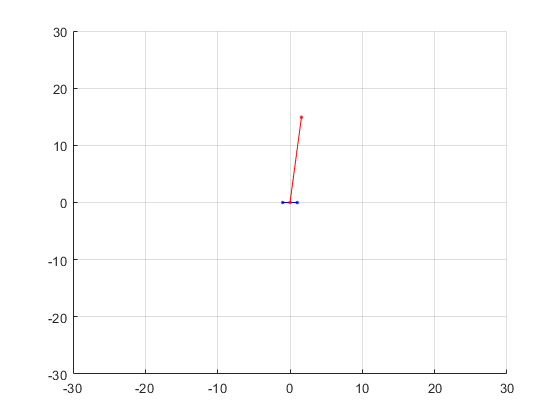

env = rlFunctionEnv(...
    ObservationInfo,ActionInfo,StepHandle,ResetHandle);

## Create Agent

RandomSeed = 0;
% numObservations = ObservationInfo.Dimension(1);
% numActions = ActionInfo.Dimension(1);
useGPU =  false;
agent = get_DDPG_Agent(ObservationInfo,numObservations, ...
	ActionInfo,numActions, ...
	RandomSeed,useGPU,Ts);

错误使用 rl.representation.rlDeterministicActorRepresentation (第 14 行)
Discrete actions not supported for deterministic actor representation.

出错 rlDeterministicActorRepresentation (第 88 行)
Rep = rl.representation.rlDeterministicActorRepresentation(...

出错 

## Create DDPG Agent

## Train

maxepisodes = 1000;
maxsteps = ceil(Tf/Ts);
trainingOptions = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'ScoreAveragingWindowLength',5,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',1000,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',95);
trainingOptions.UseParallel = true;

agentOptions.SaveExperienceBufferWithAgent = true;

doTraining = false;
if doTraining
    trainingStats = train(agent,env,trainingOptions);
end

## Simulation

 
simOptions = rlSimulationOptions('MaxSteps',500);
load(['M:\迅雷下载\Das Leben in Muenchen\', ...
	'TUM Unterricht\学期论文\MA\', ...
	'Multibody Dynamics Model-MatLab Programm\', ...
	'savedAgents\Agent490.mat'],'saved_agent')
experience = sim(env,saved_agent,simOptions);
FinalTime = experience.Observation.RigidBodyState.Time;
FinalData = experience.Observation.RigidBodyState.Data;
FinalData = reshape(FinalData,size(FinalData,1),size(FinalData,3));
FinalData = FinalData';

t_set = FinalTime;
x_set = FinalData;
FigureNr = 2;
plot_Mechanism_PostProcessing(x_set,t_set, ...
	FigureNr,ModelParameter);